# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant and to make diagnosis

#### Select and read the model file

file="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.getStateNames);
State=convertStringsToChars(States(4));
DiagnosisMethod='WASTE_EXTERNAL';

#### Compute Diagnosis Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod,'Show',true);

Fuel Impact:          3.5000 (kW)
Malfunction Cost:     3.5000 (kW)


Diagnosis Summary

Key        MF(kW)      ΔI(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPt*(kW)
——————————————————————————————————————————————————————————————————————————————
BLR       -0.7305      0.3400      0.0000     -0.7305      0.0000      0.0000
TRB       -0.0838     -0.0570      0.0000     -0.0489      0.0000      0.0000
IHE       -0.1149     -0.0390      0.0000     -0.1548      0.0000      0.0000
PMP       -0.0039      0.0120      0.0000     -0.0066      0.0000      0.0000
CND        0.0000      0.0000      3.2440      0.0100      0.0000      4.4309
ENV       -0.9331      0.2560      3.2440     -0.9309      0.0000      4.4309


Malfunction Table (kW)

 key             BLR        TRB        IHE        PMP        CND        ΔPs
————————————————————————————————————————————————————————————————————————————
 BLR          0.0000    -0.2330    -0.1142     0.0000    -0.0234     0.0000
 TRB          0.0000     0.0000

#### Show Graph Results

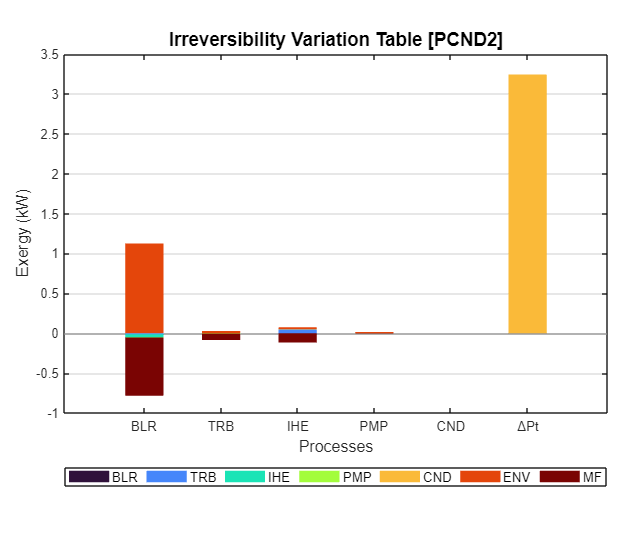

ShowGraph(res,'Graph','dit');

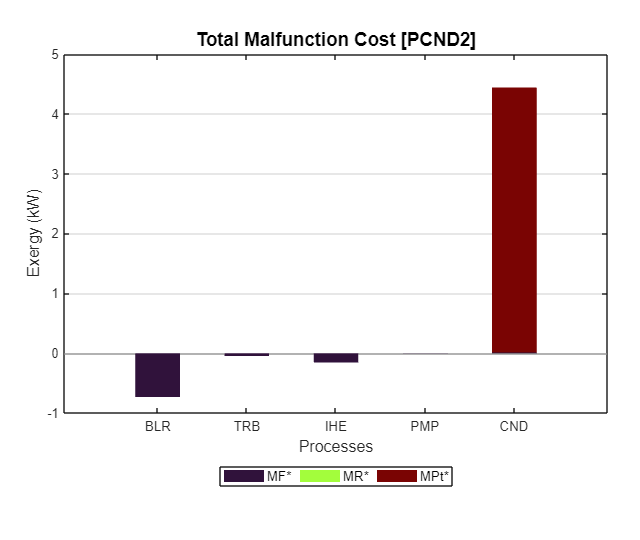

ShowGraph(res,'Graph','tmfc');